## Cold plate parameterization 

In this we will carry out a trade-study to investigate different cold plate designs and compare a layout with serpentine U-channles (Figure 1) with a layout with parallel channels (Figure 2). This sscript is used to vary geometric parameters and compare performance of the two designs in terms of heat transfer and pressure drop. 

subsection, the geometry of the cold plate can be designed, use this to vary different geometric parameters and caluculate the resulting performance parameters such as surface area relevant for heat transfer and heat transfer cofficient.

The following schematic shows the relevant input parameters that can be selected:

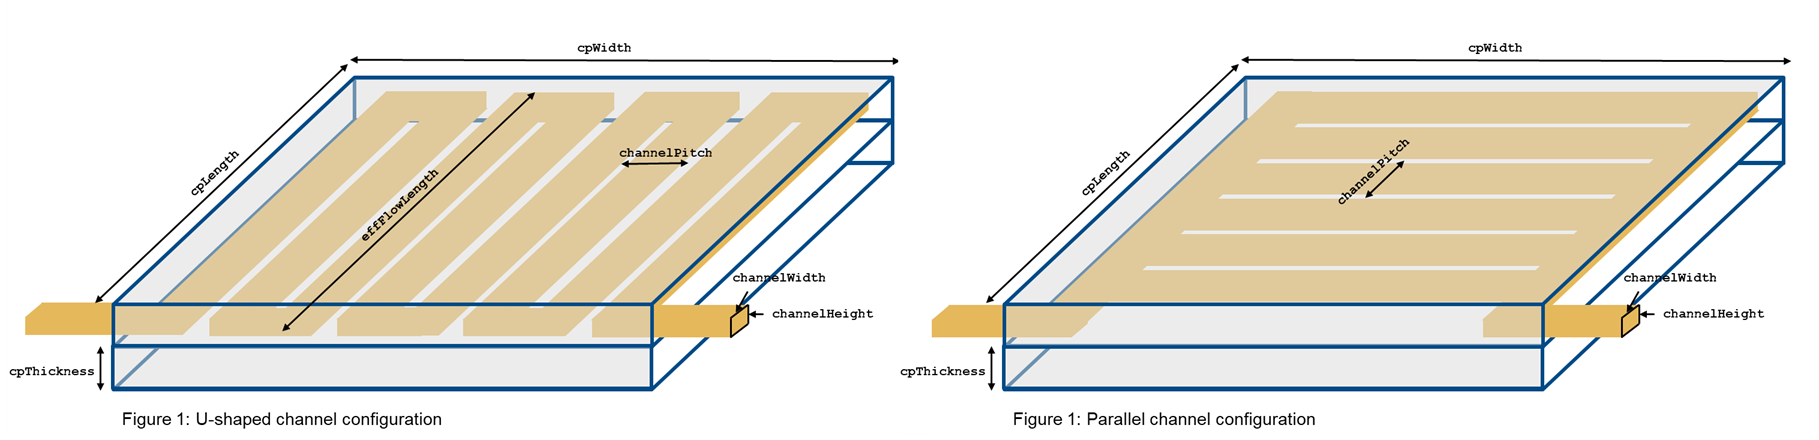

#### Geometric and material parameters of cold plate and cold plate channels:

cpLength            = simscape.Value(400, 'mm');     % (mm)
cpWidth             = simscape.Value(350, 'mm');     % (mm)
cpThickness         = simscape.Value(6, 'mm');       % (mm)

channelWidth        = simscape.Value(3, 'mm');       % (mm)
channelHeight       = simscape.Value(10, 'mm');       % (mm)
channelMargin       = simscape.Value(10, 'mm');       % mm
channelPitch        = channelWidth + simscape.Value(3, 'mm');


#### Additional parameters and cold plate material parameters

deviceD              = simscape.Value(75, 'mm');      % mm
cpK                  = simscape.Value(167, 'W/(m*K)');% (W/(m*K))
channelRoughness     = simscape.Value(15e-6, 'm');    % (m)

#### Calculate derivative parameters

This sections calculates derived geometric parameters from the above selected values. Additionally to account for additional pressure losses for the bends in both configurations, we will use an approach using the equivalent length factor that can be accounted for in the pipe components. This was chosen, since the Simscape pipe blocks allow for additional fittings to be accounted for using the equivalent length method. 

% U-shaped channels
effFlowLengthU        = cpLength - 2*channelMargin;                                 % Effective flow length of channels for U-shaped configuration
numPassesU            = floor((cpWidth - 2*channelMargin)/(2*channelPitch));        % Number of channel "U" passes based on the channel pitch for U-shaped configuration
channelLengthU        = numPassesU*2*effFlowLengthU;                                % Derived total channel length for U-shaped configuration  
channelHTCSurfaceAreaU= channelLength*2*(channelWidth+channelHeight);               % Channel surface area for convective heat transfer for U-shaped configuration

% Parallel channels
channelLengthP        = cpWidth - 2*channelMargin;                                  % Flow length of each parallal channel for parallel configuration
numChannelsP          = floor((cpLength - 2*channelMargin)/channelPitch);
channelHTCSurfaceAreaP= channelLengthP*2*(channelWidth+channelHeight)*numChannelsP; % Channel surface area for convective heat transfer for U-shaped configuration

% Shared parameters
channelArea           = channelHeight*channelWidth;                                 % Channel cross-sectional area 
channelDh             = 2*channelWidth*channelHeight/(channelHeight+channelWidth);  % Channel hydraulic diameter 
cpDeviceSurfaceArea   = pi*(deviceD/2)^2;                                           % Device surface area

% Calculating additional equivalent length to determine pressure drop
% U-shaped channels
numBendU              = numPassesU*4;                                               % Number of 90 degree bends in U-shaped configuration
equivalentLengthU     = numBendU*60*channelDh;                                      % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow
% Parallel channels
numBendP              = 2;                                                          % Number of 90 degree bends in parallel channel configuration
equivalentLengthP     = numBendP*60*channelDh;                                      % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow

#### Calculate performance

The convective heat transfer coefficient in the cold channels can be determined using the Gnielinksi correlation. This is the same approach that is being used inside the Pipe (TL) component. For simplicity, we are using the fluid properties at an assumed inlet temperature of 25°C. The Reynolds number laminar flow upper limit and the Reynolds number turbultent flow lower limit is assumed to be at 2000 and 4000 respectively. This is then used to determine the thermal resistance of the convective heat transfer path. 

htcU = calculateHTCPipe(channelDh,channelArea, mDot, 2000, 4000, kCoolant,channelRoughness/channelDh,muCoolant,PrCoolant);
htcP = calculateHTCPipe(channelDh,channelArea, mDot/numChannelsP, 2000, 4000, kCoolant,channelRoughness/channelDh,muCoolant,PrCoolant);
RconvU  = 1/(htcU*channelHTCSurfaceAreaU);
RconvP  =  1/(htcP*channelHTCSurfaceAreaP);

The thermal resistance due to conduction is then determined using the cold plate specifications and its material properties

Rcond  = cpThickness/(cpK*cpDeviceSurfaceArea);

The two combines give the total resistance

RtotalU = RconvU+Rcond;
disp(RtotalU.value('deltaK/W'))

    0.0089



RtotalP = RconvP+Rcond;
disp(RtotalP.value('deltaK/W'))

    0.0175

